clc;
clear;
path = 'csv/on';
files = dir(fullfile(path,'*.csv'));
L = length (files);

## Read csv data

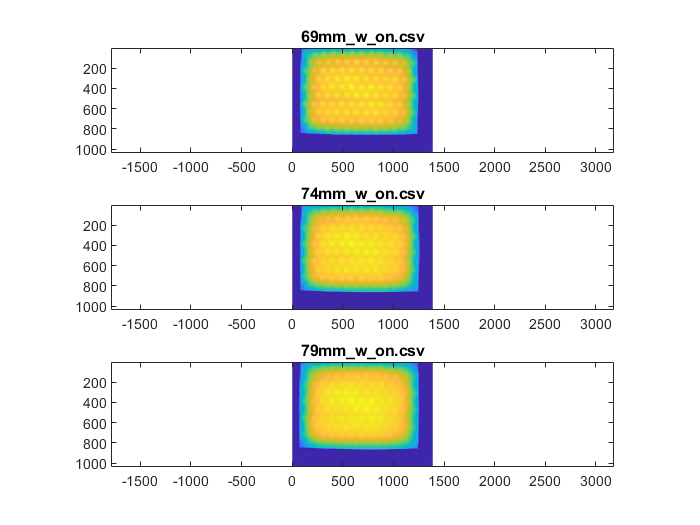

csv{L} = [];
for i=1:L
    csv{i} =readLdata(strcat(path,'\',files(i).name));
    % process the image in here
end

f1 = figure;

for i=1:L
    subplot(L,1,i);
    imagesc(csv{i});
    title(files(i).name,'Interpreter','none');
    axis equal;
end

## Process data

M{L} = [];
G{L} = [];
bw{L} = [];

for i=1:L
    
    
    M{i}=lensdistort(csv{i},-0.07);
    
    
    G{i} = mat2gray(M{i});
    bw{i} = imbinarize(G{i}, graythresh(G{i})/2);
    M{i} = M{i}.*bw{i};
    M{i}(M{i}==0) = NaN;
    M{i} = trim(M{i});
    
    
    
end


## Plot corrected data

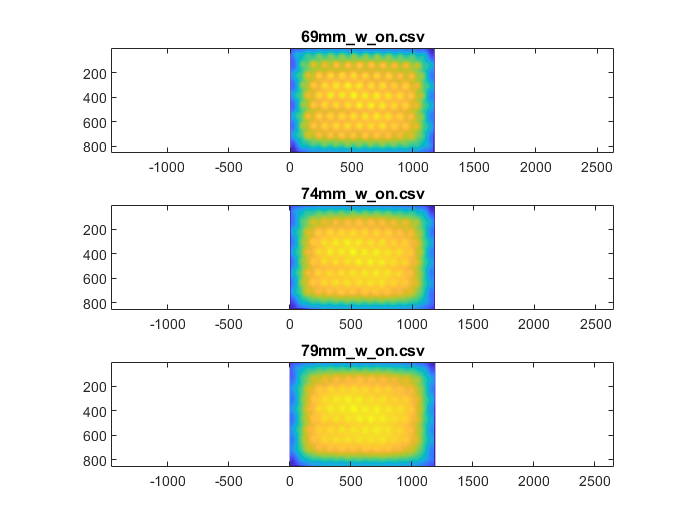


f2 = figure;

for i=1:L
    subplot(L,1,i);
    imagesc(M{i});
    title(files(i).name,'Interpreter','none');
    axis equal;
    
end

## Evaluate data

lMean{L} = [];
rmes{L} = [];
w{L} = [];
h{L} = [];
W{L} = [];
H{L} = [];


for i=1:L
    lMean{i} = nanmean(nanmean(M{i}));
    rmse{i} = sqrt(nanmean(nanmean((M{i}-lMean{i}).^2)))/lMean{i};
end

lMean

lMean = 1×3 cell array
    {[2.6524e+03]}    {[2.6025e+03]}    {[2.5612e+03]}


rmse

rmse = 1×3 cell array
    {[0.2237]}    {[0.2297]}    {[0.2346]}



%round(N/4:3*N/4)

for i=1:L
    w{i} = length(M{i}(1,:));
    h{i} = length(M{i}(:,1));
    W{i} = round(w{i}/4:3*w{i}/4);
    H{i} = round(h{i}/4:3*h{i}/4);
    lMeanCtr{i} = nanmean(nanmean(M{i}(H{i},W{i})));
    rmseCtr{i} = sqrt(nanmean(nanmean((M{i}(H{i},W{i})-lMean{i}).^2)))/lMean{i};
end

lMeanCtr

lMeanCtr = 1×3 cell array
    {[3.1704e+03]}    {[3.1488e+03]}    {[3.1267e+03]}


rmseCtr

rmseCtr = 1×3 cell array
    {[0.1996]}    {[0.2120]}    {[0.2223]}


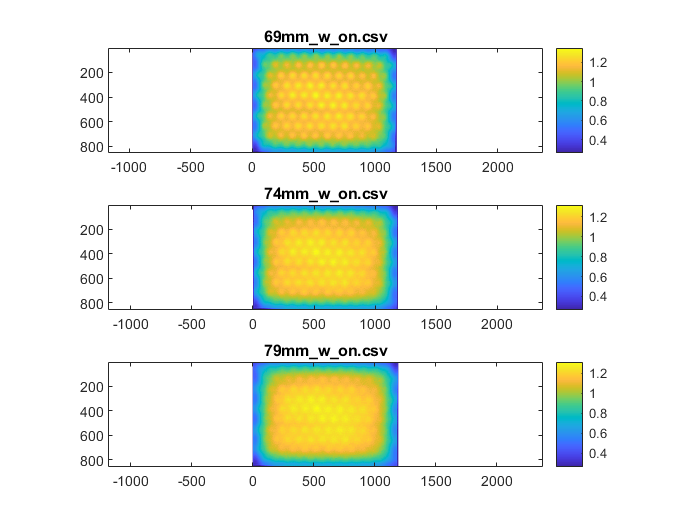


f3 = figure;



for i=1:L
    subplot(L,1,i);
    E{i} = (M{i}./lMean{i});
    imagesc(E{i});
    %ax = gca;
    %ax.CLim = [1000 3500];
    colorbar
    title(files(i).name,'Interpreter','none');
    
    axis equal;

end


% set(gcf,'CurrentCharacte

%r',char(1));
% h=datacursormode;
% set(h,'DisplayStyle','datatip','SnapToData','off');
% waitfor(gcf,'CurrentCharacter',char(32));
% s = getCursorInfo(h);
% x=s.Position;

function ret = readLdata(filename)
% read LMK Labsoft csv Data
copyfile( filename, 'comma2point.txt' );
comma2point_overwrite( 'comma2point.txt' );
ret = dlmread('comma2point.txt');
end

function ret = trim(m)
% trim all NaNs from Matrix M
ret = m(:,any(~isnan(m)));  % for columns
ret = ret(any(~isnan(ret),2),:);   %for rows
end